## Hilbert envelopes wit and without averaging first 

We start by making a discrete time vector, at which the signal will be sampled. 

clear
time = 0.001:0.001:3; % one second of discrete time, sampled at 1000 Hz

now, we make a time series of Brownian noise (biorealistic) time series not unlike EEG/LFP, representing one trial of neural mass data

temp1 = rand(size(time))-.5; % zero-center the white noise, because we use cumulative sum later
brownsig = cumsum(temp1);  % Brownian noise is the cumulative sum of white noise
figure
brownsig = detrend(brownsig);
plot(time, brownsig),title('One second of Brownian noise (simulated neural time series)') 

Now we make 3 simple signals, to be added to the brownian noise.

SNR = .6;  
Sin7_5Hz = sin(2*pi*time*7.5).*SNR; % a 7.5 Hz sine wave
sumsig = brownsig; 
sumsig(501:2500) = brownsig(501:2500) + Sin7_5Hz(501:2500);
figure
plot(time, brownsig),title('One second of Brownian noise (simulated neural time series)') 
hold on
plot(time, sumsig),title('One second of Brownian noise with 7.5 Hz sine wave') 

[hilbamp, phase, complex] = freqtag_HILB(sumsig, 7.5, 8, 1, 1, 1000);

Now, put everything in a loop, with 30 trials. 

First, do averaging, then do hilbert

Sin7_5Hz = sin(2*pi*time*7.5).* SNR

avgsig = zeros(1,3000);  

for trial = 1:30
   temp1 = rand(size(time))-.5; % zero-center the white noise, because we use cumulative sum later
   brownsig = cumsum(temp1);  % Brownian noise is the cumulative sum of white noise
   brownsig = detrend(brownsig);
   sumsig = brownsig; 
   jitter = randi([1 30]);
   sumsig(501:2500) = brownsig(501:2500) + Sin7_5Hz(501+jitter:2500+jitter);
   
  % [hilbamp, phase, complex] = freqtag_HILB(sumsig, 7.5, 8, 1, 0, 1000); pause
      
    avgsig = avgsig + sumsig; 
    
    [hilbamp, phase, complex] = freqtag_HILB(avgsig, 7.5, 8, 1, 0, 1000);
    
    plot(time, avgsig), hold on
    plot(time, hilbamp), title(num2str(trial)), hold off, pause
    
end

Now, put everything in a loop, with 30 trials. 

First, do hilbert, then do averaging


Sin7_5Hz = sin(2*pi*time*7.5).* SNR

hilbavg = zeros(1,3000);  

figure
 
for trial = 1:30
   temp1 = rand(size(time))-.5; % zero-center the white noise, because we use cumulative sum later
   brownsig = cumsum(temp1);  % Brownian noise is the cumulative sum of white noise
   brownsig = detrend(brownsig);
   sumsig = brownsig; 
   jitter = randi([1 30]);
   sumsig(501:2500) = brownsig(501:2500) + Sin7_5Hz(501+jitter:2500+jitter); 
   
   [hilbamptrial, phase, complex] = freqtag_HILB(sumsig, 7.5, 8, 1, 0, 1000);
   
    hilbavg = hilbavg + hilbamptrial; 
    
    plot(time, hilbavg), title(num2str(trial)), hold off, pause
    
end

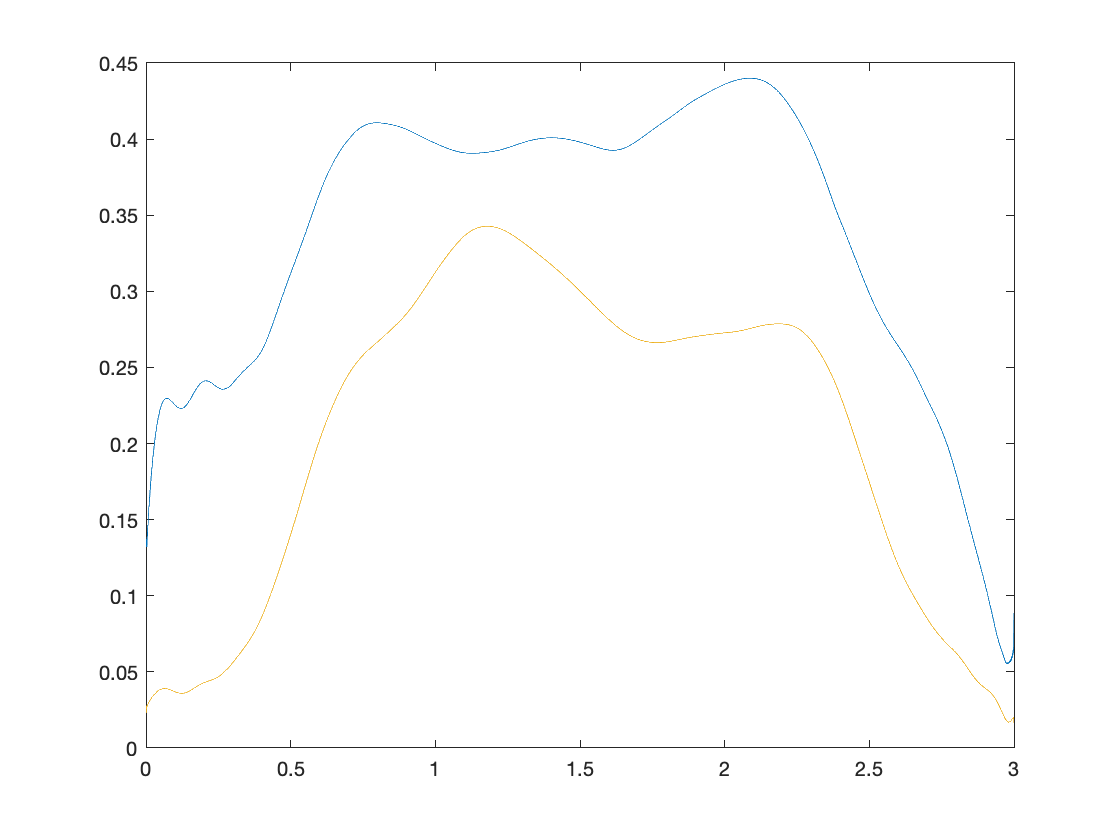

figure
plot(time, hilbamp./30)
hold on 

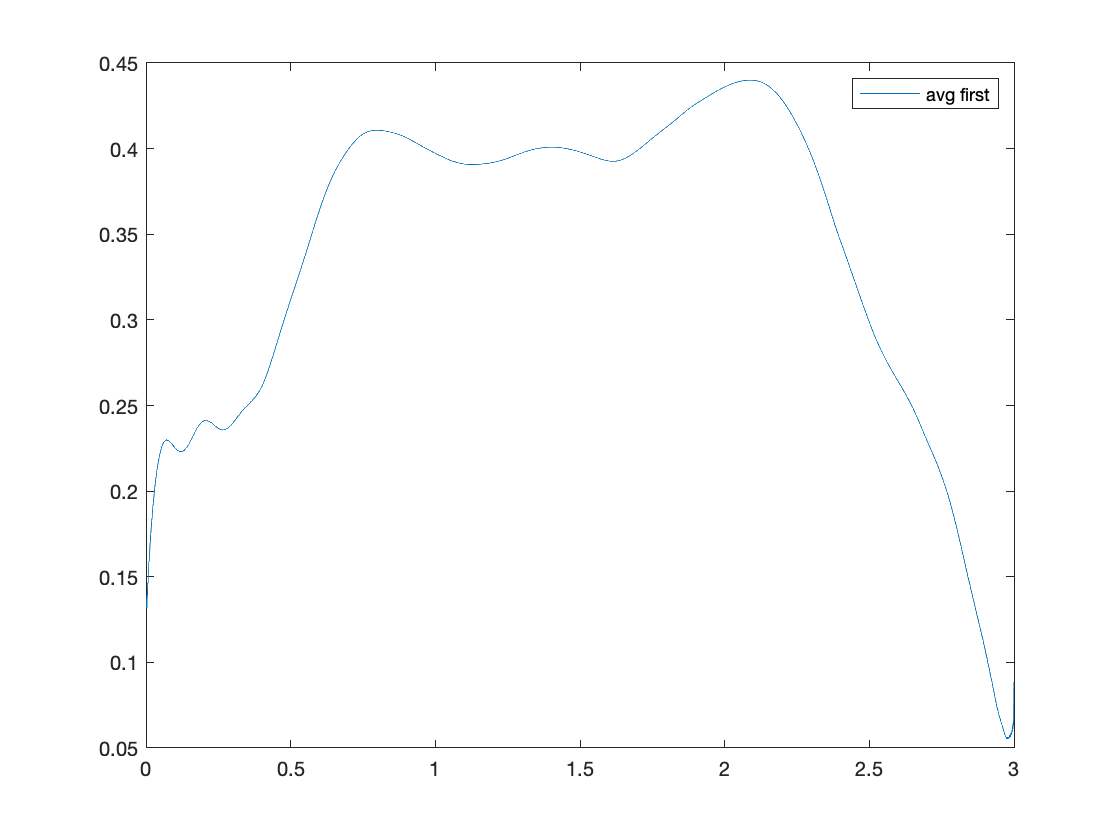

plot(time, hilbavg./30)
legend('avg first', 'hilbert first')